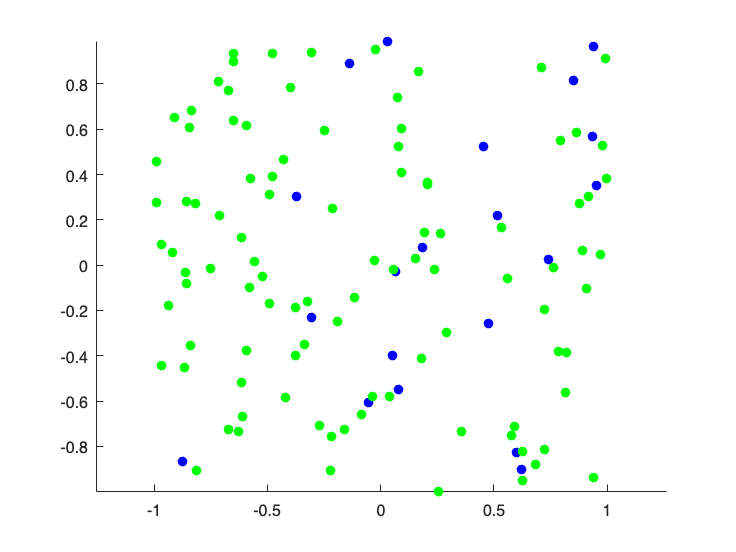

clear;

% Parametros del sistema
NL = 20; % Numero inicial de lobos
NO = 100; % Numero inicial de ovejas
T = 100; % Cantidad de iteraciones
deltaL = 0.1; % Paso maximo para lobos
deltaO = 0.1; % Paso maximo para ovejas
rho = 0.05; % Radio de cercania
pPlusL = 1; % Probabilidad de que un lobo genere un nuevo lobo
pPlusO = 0.02; % Probabilidad de reproduccion de ovejas
pMinusL = 0.05; % Probabilidad de muerte de lobos sin presa

% Preparamos vectores para el plot de la evolucion del sistema
NumeroLobos = zeros(1,T);
NumeroOvejas = zeros(1,T);
t = zeros(1,T);
NumeroLobos(1) = NL;
NumeroOvejas(1) = NO;
t(1) = 1;

% Inicialización de lobos y ovejas
lobos.x = random('Uniform', -1, 1, 1, NL);
lobos.y = random('Uniform', -1, 1, 1, NL);
lobos.status = zeros(1, NL);

ovejas.x = random('Uniform', -1, 1, 1, NO);
ovejas.y = random('Uniform', -1, 1, 1, NO);
ovejas.status = zeros(1, NO);
figure(1)
scatter(lobos.x, lobos.y, 'b', 'filled'); hold on; 
scatter(ovejas.x, ovejas.y, 'g', 'filled'); 
hold off;
axis equal;

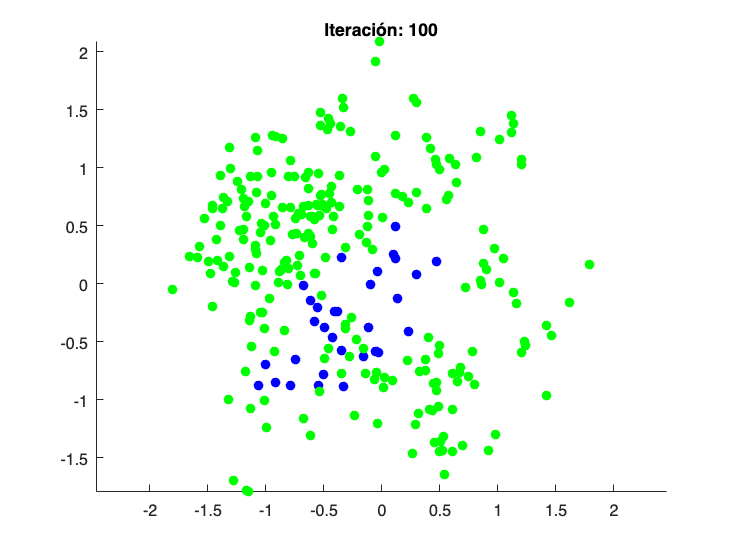


% Bucle principal
for ii = 2:T
    % Movimiento de lobos y ovejas
    rrl = deltaL * rand(1, NL);
    phl = 2 * pi * rand(1, NL);
    rro = deltaO * rand(1, NO);
    pho = 2 * pi * rand(1, NO);

    lobos.x = lobos.x + rrl .* cos(phl);
    lobos.y = lobos.y + rrl .* sin(phl);
    ovejas.x = ovejas.x + rro .* cos(pho);
    ovejas.y = ovejas.y + rro .* sin(pho);

    % Verificar cercania y hacer todo lo de las instrucciones
    for l = 1:NL
        for o = 1:NO
            distance = sqrt((lobos.x(l) - ovejas.x(o))^2 + (lobos.y(l) - ovejas.y(o))^2);
            
            % Caza de ovejas
            if distance < rho
                lobos.status(l) = 1; % Lobo se comio la oveja
                ovejas.status(o) = 1; % Oveja fue comida
                % Generar nuevo lobo con probabilidad pPlusL
                if rand() < pPlusL
                    NL = NL + 1;
                    step = deltaL * rand();
                    phi = 2*pi*rand();
                    lobos.x(NL) = lobos.x(l) + step * cos(phi);
                    lobos.y(NL) = lobos.y(l) + step*sin(phi);
                    lobos.status(NL) = 1;
                end
            end
        end
    end
    
    % Reproduccion de ovejas con probabilidad pPlusO
    for o = 1:NO
        if ovejas.status(o) == 0 && rand() < pPlusO
            NO = NO + 1;
            step = deltaO * rand();
            phi = 2*pi*rand();
            ovejas.x(NO) = ovejas.x(o) + step*cos(phi);
            ovejas.y(NO) = ovejas.y(o) + step*sin(phi);
            ovejas.status(NO) = 0;
        end
    end
    
    % Muerte de lobos sin presa con probabilidad p-
    for l = 1:NL
        if rand() < pMinusL && lobos.status(l) == 0
            lobos.status(l) = 2; % Lobo muere
        end
    end
    

    % Eliminar lobos y ovejas muertos de los structs
    lobos.status(lobos.status == 1) = 0;
    lobos.x = lobos.x(lobos.status == 0);
    lobos.y = lobos.y(lobos.status == 0);
    lobos.status = lobos.status(lobos.status == 0);

    ovejas.x = ovejas.x(ovejas.status == 0);
    ovejas.y = ovejas.y(ovejas.status == 0);
    ovejas.status = ovejas.status(ovejas.status == 0);
    
    % Actualiza las poblaciones
    NL = sum(lobos.status == 0);
    NO = sum(ovejas.status == 0);
    
    % Guardamos datos del estado para el plot final
    NumeroLobos(ii) = NL;
    NumeroOvejas(ii) = NO;
    t(ii) = ii;

    % Animacion
    figure(1)
    scatter(lobos.x, lobos.y, 'b', 'filled'); hold on; 
    scatter(ovejas.x, ovejas.y, 'g', 'filled'); hold off;
    title(['Iteración: ' num2str(ii)]); % Agrega el número de iteración al título
    axis equal;
    pause(0.001);
end

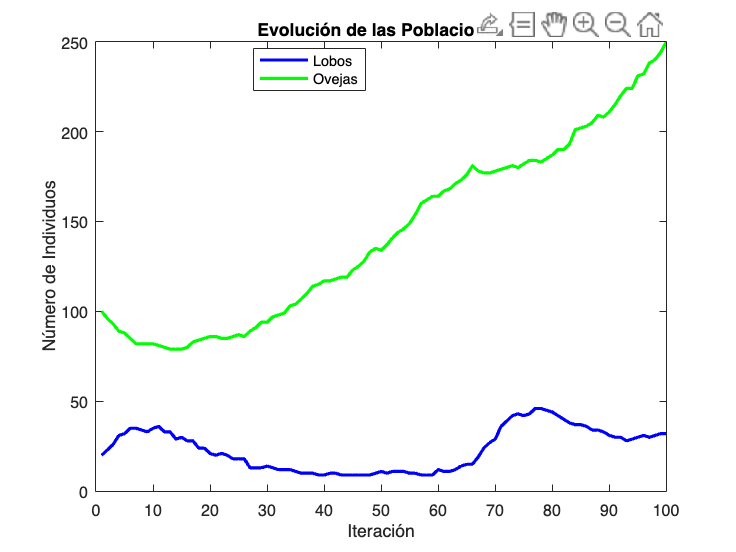


plot(t, NumeroLobos, 'b', 'LineWidth', 2, 'DisplayName', 'Lobos'); hold on;
plot(t, NumeroOvejas, 'g', 'LineWidth', 2, 'DisplayName', 'Ovejas'); hold off;

xlabel('Iteración');
ylabel('Número de Individuos');
title('Evolución de las Poblaciones');
legend('Location', 'Best');